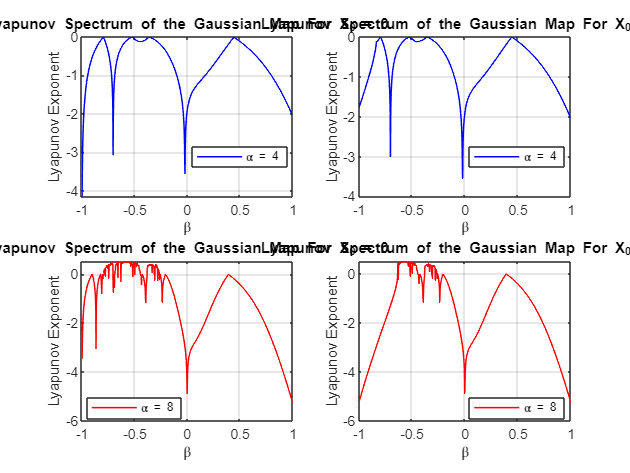

% Define parameters
alpha_values = [4, 8];
% Values of Beta
beta_values = linspace(-1, 1, 1000);

% Initialize Lyapunov exponents array
lyapunov_exponents = zeros(length(alpha_values), length(beta_values));
num_x0 = 2;
for alpha_idx = 1:length(alpha_values)
    alpha = alpha_values(alpha_idx);

    for beta_idx = 1:length(beta_values)
        beta = beta_values(beta_idx);

        % Initialize variables
        x0_values = [0, -1];
        num_iterations = 1000;
        sum_log_derivative = zeros(1, num_x0);

        for x0_idx = 1:num_x0
            x0 = x0_values(x0_idx);
            x = x0;

            for n = 1:num_iterations
                % Gaussian map iteration
                x  = exp(-alpha*x^2) + beta;

                % Compute the derivative of the map
                map_derivative = 2 * alpha * x *  exp(-alpha*x^2);

                % Update the sum of logarithmic derivatives
                sum_log_derivative(x0_idx) = sum_log_derivative(x0_idx) + log(abs(map_derivative));
            end

            % Compute the average logarithmic derivative for this x0
            average_log_derivative = sum_log_derivative(x0_idx) / num_iterations;

            % Store Lyapunov exponent
            lyapunov_exponents(beta_idx, x0_idx, alpha_idx) = average_log_derivative;
        end

    end
end

% Plot the Lyapunov spectrum
figure;
subplot(2,2,1)
plot(beta_values, lyapunov_exponents(:, 1, 1), 'b', 'LineWidth', 1, 'DisplayName', '{\alpha} = 4');

xlabel('{\beta}');
ylabel('Lyapunov Exponent');
title('Lyapunov Spectrum of the Gaussian Map For X_{0} = 0');
legend('Location', 'best');
grid on;

subplot(2,2,2)
plot(beta_values, lyapunov_exponents(:, 2, 1), 'b', 'LineWidth', 1, 'DisplayName', '{\alpha} = 4');

xlabel('{\beta}');
ylabel('Lyapunov Exponent');
title('Lyapunov Spectrum of the Gaussian Map For X_{0} = -1');
legend('Location', 'best');
grid on;

subplot(2,2,3)
plot(beta_values, lyapunov_exponents(:, 1, 2), 'r', 'LineWidth', 1, 'DisplayName', '{\alpha} = 8');
xlabel('{\beta}');
ylabel('Lyapunov Exponent');
title('Lyapunov Spectrum of the Gaussian Map For X_{0} = 0');
legend('Location', 'best');
grid on;

subplot(2,2,4)
plot(beta_values, lyapunov_exponents(:, 2, 2), 'r', 'LineWidth', 1, 'DisplayName', '{\alpha} = 8');

xlabel('{\beta}');
ylabel('Lyapunov Exponent');
title('Lyapunov Spectrum of the Gaussian Map For X_{0} = -1');
legend('Location', 'best');
grid on;